# Sistema Realimentados

# EP25 - Projeto do controlador proporcional derivativo

Data: 13 de junho

ARTHUR LORENCINI BERGAMASCHI

PEDRO GABRIEL GAMBERT DA SILVA

## Questão 1

Seja a FT 


$$G\left(s\right)=\frac{2}{\left(s+1\right)\left(s+1\right)\left(5s+1\right)}$$


## Projete um controlador C1 do tipo PI que atenda as especificações:

• Erro nulo em regime para entrada degrau

• Tempo de estabelecimento ≤40 segundos.

• Sobrelevação menor que 40%

s = tf('s');
g1 = 2/((s+1)*(s+1)*(5*s+1));

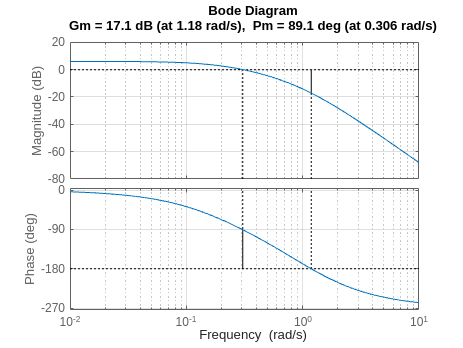

margin(g1)
grid;

% Ao analisar o gráfico de bode,
% Queremos abaixar o gráfico de módulo cerca de 4.5dB, para termos uma
% MF = 60 graus 
% Uma margem de fase razoável. Poderíamos ter diminuído mais.
% Logo kp = 10^(4.5/20)
kp = 1.67;
% Com isso, vemos o nosso wg para 0dB.
zero = 0.5;
% Vimos que se usarmos a regra de colocar uma década antes
% não teremos um controlador bom
ki_1 = kp*zero/10

ki_1 = 0.0835

ki_2 = kp*zero/5

ki_2 = 0.1670

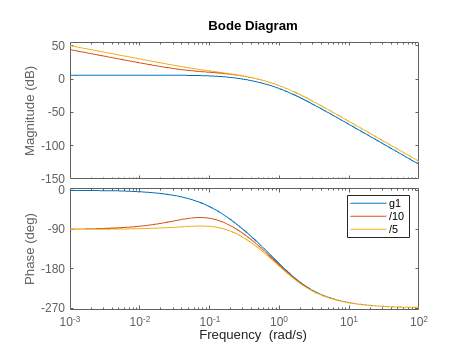

c1_1 = kp + ki_1/s;
c1_2 = kp + ki_2/s;
bode(g1,c1_1*g1,c1_2*g1)
legend('g1','/10','/5')

c1 = c1_2;

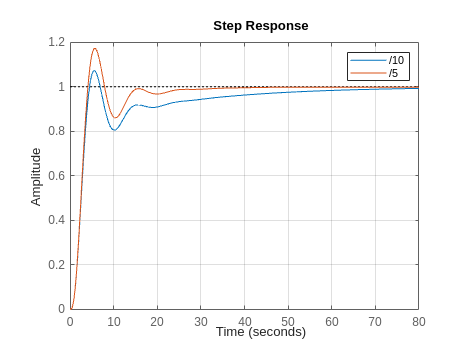

% Definindo as funções para serem plotadas com step
m1_1 = feedback(c1_1*g1,1);
m1_2 = feedback(c1_2*g1,1);
step(m1_1,m1_2);grid;
legend('/10','/5')

m1 = m1_2;

Mostre o gráfico de Bode de G e de C1G, explicando o projeto e o efeito do PI sobre a Margem de fase.

Mostre no gráfico a localização do zero do PI.

## Projete um controlador C2 do tipo PD que junto com C1 atenda as especificações:

• Erro nulo em regime para entrada degrau

• Tempo de estabelecimento ≤20 segundos.

• Sobrelevação menor que 5%

Mostre o gráfico de Bode de C1G e de C2C1G, explicando o projeto e o efeito do PD sobre a Margem de fase.

Mostre no gráfico a localização do zero do PI e do PD.

% Função com C1*G
g2 = c1*g1;
% o kp do PD escolhido para dar uma margem de fase bem baixa.
% e satisfazer o tempo de resposta.
kp2 = 1.6;
F = 1.1;
% Igualamos a nova frequência de cruzamento ao zero do PI
wg = zero;
% Escolhemos o zero do pd perto do PI
% parar aumentar a MF e diminuir a sobreelevação
zero_pd = wg*F;
% Definindo o kd
kd = kp2/zero_pd

kd = 2.9091

% Analisando o efeito de kp do pd para C1*G
bodeplot(g2,kp2*g2);grid;
% Montando o controlador
c2 = kp2 + kd*s

c2 =
 
  2.909 s + 1.6
 
Continuous-time transfer function.
Model Properties


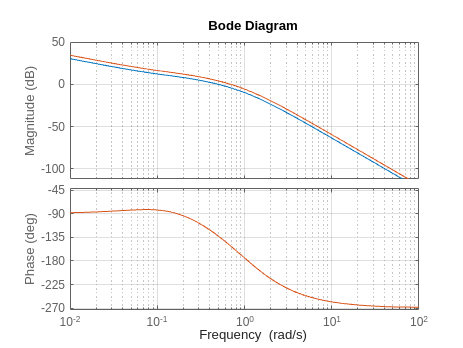

m2 = feedback(kp2*g2,1);
m3 = feedback(c2*g2,1);
yline(1.05, '--'); % '--' Vendo a linha dos 5%

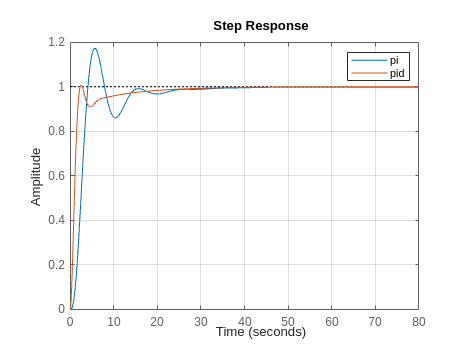

step(m1,m3);grid;
legend('pi','pid')

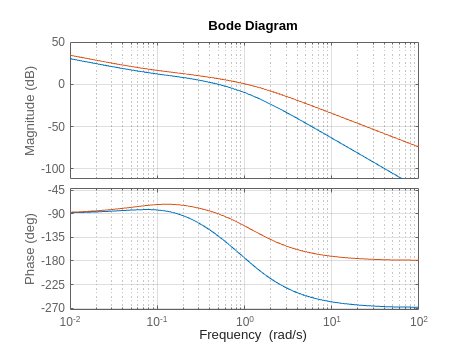

% Mostre o gráfico de Bode de C1G e de C2C1G, explicando o projeto e o efeito do PD sobre a Margem de fase.
bodeplot(g2,c2*g2);grid;

A Margem de Fase aumentou com o zero do PD em -1.